# ocalize 2-D Lidar Scans in Map

Load a MAT file containing 2-D lidar scans and a warehouse map into the workspace.

data = load("wareHouse.mat");
scans = data.wareHouseScans;

Create a `lidarscanmap` object.

scanMapObj = lidarscanmap;

Add the scans from the input data to the `scanMapObj` object by using the [`addScan`](docid:lidar_ref#mw_436dfe76-c72b-42e1-8e32-8efa7262eec5) function.

for currentID = 1:70
    addScan(scanMapObj,scans{currentID});
end

Display the warehouse map.

ax = show(scanMapObj,ShowTrajectory=false);
hold on

Find the absolute pose of the first scan in the map by using the [`findPose`](docid:lidar_ref#mw_823c19b6-4359-42a7-99cd-9a1d5c88795b) function. Specify the pose estimate of the scan as [0 0] and the search radius as 5 meters.

absPose = findPose(scanMapObj,scans{1},[0 0],SearchRadius=5);

Display the pose of the first scan in the map.

showShape("circle",[absPose(1:2) 0.2],Color="g",Parent=ax)

Iterate the previous two steps to localize the remaining scans in the map and visualize the results.

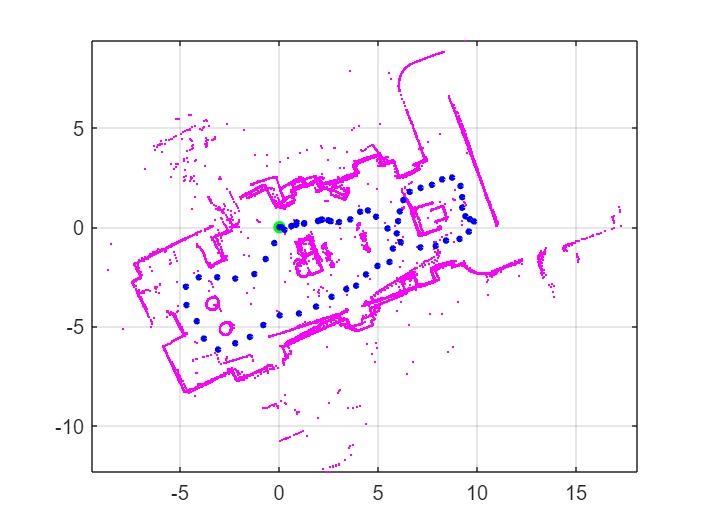

for n = 2:numel(scans)
    currentScan = scans{n};

    % Use the absolute pose of the previous scan as the pose estimate for
    % the next scan
    poseEstimate = absPose(1:2);
    absPose = findPose(scanMapObj,currentScan,poseEstimate,SearchRadius=5);

    % Display the pose of the current scan in the map
    pose = [absPose(1:2) 0.05];
    showShape("circle",pose,Color="b")
end
hold off

*Copyright 2021 The MathWorks, Inc.*